ciqData = readtable('C:\GIT\LOEquity\Data.csv');
ciqData.IQ_PAYOUT = ciqData.IQ_DIV_SHARE - ciqData.CF_DECR_CAP_STOCK - ciqData.CF_INCR_CAP_STOCK;
ciqData.BBG_BB = - ciqData.CF_DECR_CAP_STOCK - ciqData.CF_INCR_CAP_STOCK;

INCOME_STATEMENT = 6 : 14;
BALANCE_SHEET = 15 : 22;
CASH_FLOW = 23 : 25;
RATIOS = 26 : 31;

Follow block was done July 6: 

First regression (units are $s per share): 


$$\begin{array}{l}
{\mathrm{bb}}_t =\alpha +\beta_1 \cdot {\mathrm{bb}}_{t-1} +\beta_2 \cdot {\mathrm{EBIT}}_t +\varepsilon_t \\
\beta_1 =-5\ldotp 8\\
\beta_1 =0\ldotp 43\\
\beta_2 =0\ldotp 33\\
R^2 =0\ldotp 60
\end{array}$$


y0 = ciqData.BBG_BB; % IQ_DIV_SHARE, DVD_SH_12M, BBG_BB, IQ_PAYOUT
X0 = ciqData.IQ_EBIT; % IQ_EBIT, IQ_BASIC_EPS_EXCL, 
y = y0(2:end,1); 
X = [y0(1:end-1,1),X0(2:end,1)]; 
o = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 
rho = autocorr(o.r,'NumLags',2); 
% Output Arguments:
%   acf - Sample ACF. Vector of length NumLags+1 of values computed at lags
%       0,1,2,...,NumLags. For all y, acf(1) = 1 at lag 0.
%   lags - Vector of lag numbers of length NumLags+1 used to compute acf.
%   bounds - Two-element vector of approximate upper and lower confidence
%       bounds, assuming that y is an MA(NumMA) process.
%   h - Vector of handles to plotted graphics objects. AUTOCORR plots the
%       ACF when the number of output arguments is 0 or 4.

Second regression (units are $s per share): 


$$\begin{array}{l}
{\textrm{bb}}_t =\alpha +\beta_1 \cdot {\textrm{bb}}_{t-1} +\beta_2 \cdot {\textrm{bb}}_{t-2} +\beta_3 \cdot {\textrm{EBIT}}_t +\varepsilon_t \\
\beta_1 =-4\ldotp 13\\
\beta_1 =0\ldotp 309\\
\beta_2 =0\ldotp 297\\
\beta_3 =0\ldotp 234\\
R^2 =0\ldotp 634
\end{array}$$


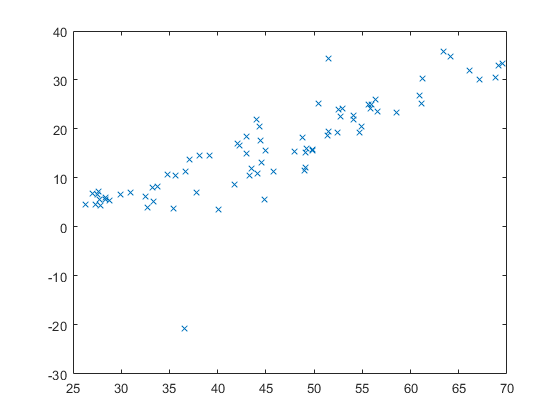

% spec 2
y = y0(3:end,1); 
X = [y0(2:end-1,1),y0(1:end-2,1),X0(3:end,1)]; 
o = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 
rho = autocorr(o.r,'NumLags',2); 
figure(1); plot(X(:,3),y,'x')

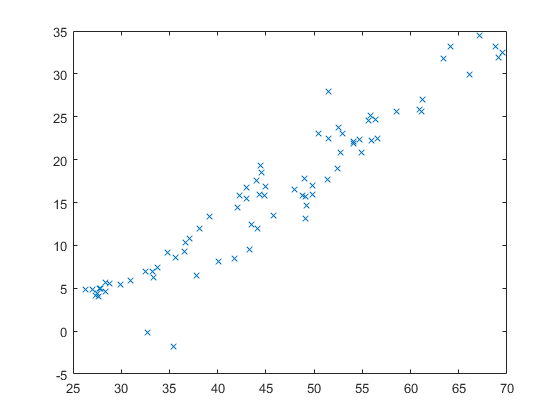

figure(2); plot(X(:,3),o.yhat,'x')

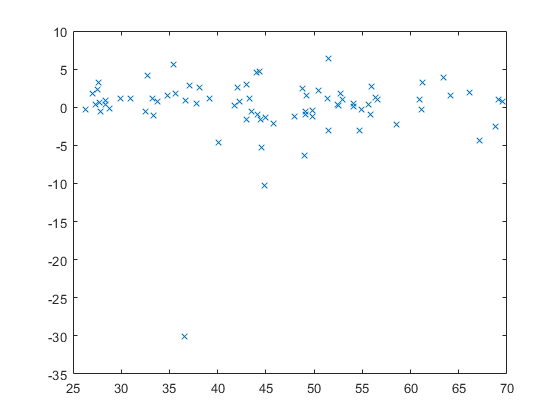

figure(3); plot(X(:,3),o.r,'x')

Third regression (units are $s per share): 


$$\begin{array}{l}
{\textrm{bb}}_t =\alpha +\beta_1 \cdot {\textrm{bb}}_{t-1} +\beta_2 \cdot {\textrm{EBIT}}_t +\beta_3 \cdot {\mathrm{ROE}}_t +\varepsilon_t \\
\beta_1 =-10\ldotp 65\\
\beta_1 =0\ldotp 432\\
\beta_2 =0\ldotp 227\\
\beta_3 =0\ldotp 626\\
R^2 =0\ldotp 74
\end{array}$$


% spec 3
y0 = ciqData.BBG_BB; % IQ_DIV_SHARE, DVD_SH_12M, BBG_BB, IQ_PAYOUT
% X0 = [ciqData.IQ_EBIT,ciqData.IQ_CASH_OPER,ciqData.IQ_CF_SHARE,ciqData.IQ_RETURN_EQUITY,ciqData.IQ_GROSS_MARGIN]; 
X0 = [ciqData.IQ_EBIT,ciqData.IQ_RETURN_EQUITY];
y = y0(3:end,1); 
%X = [y0(2:end-1,1),y0(1:end-2,1),X0(3:end,1),X0(3:end,2)]; 
X = [y0(2:end-1,1),X0(3:end,1),X0(3:end,2)]; % X0(3:end,2),
o = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 
rho = autocorr(o.r,'NumLags',2); 
figure(1); plot(X(:,3),y,'x')

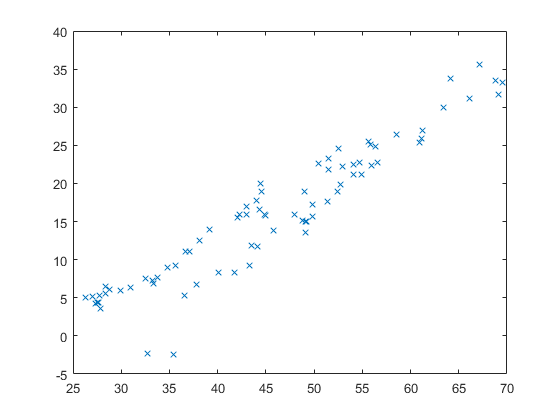

figure(2); plot(X(:,3),o.yhat,'x')

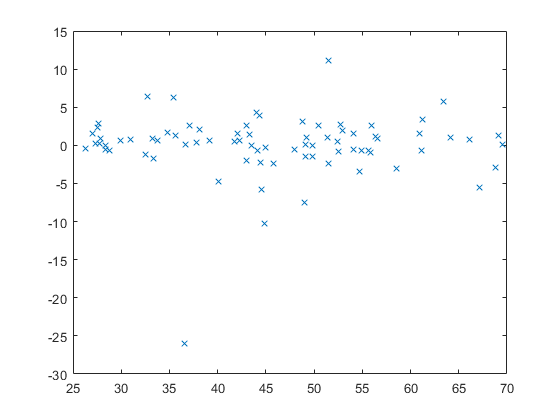

figure(3); plot(X(:,3),o.r,'x')

Fourth regression (units are $s per share): 


$$\begin{array}{l}
{\textrm{bb}}_t =\alpha +\beta_1 \cdot {\textrm{bb}}_{t-1} +\beta_2 \cdot {\textrm{EBIT}}_t +\beta_3 \cdot \left({\mathrm{CF}}_t -0\ldotp 5\cdot \left({\mathrm{CF}}_{t-1} +{\mathrm{CF}}_{t-2} \right)\right)+\varepsilon_t \\
\alpha =-6\ldotp 36\\
\beta_1 =0\ldotp 402\\
\beta_2 =0\ldotp 343\\
\beta_3 =0\ldotp 059\\
R^2 =0\ldotp 6161
\end{array}$$


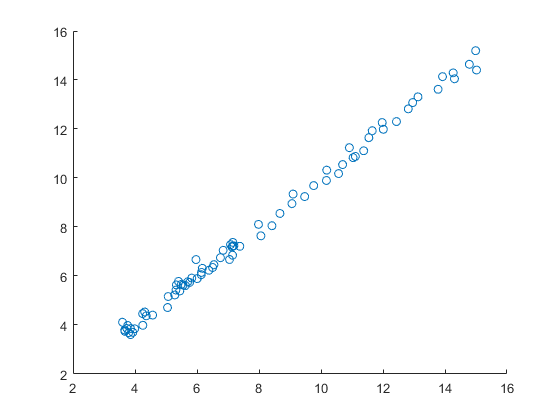

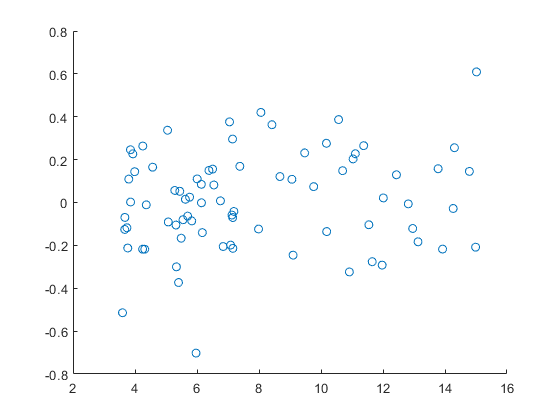

% spec 4
y0 = ciqData.BBG_BB; % IQ_DIV_SHARE, DVD_SH_12M, BBG_BB, IQ_PAYOUT
% X0 = [ciqData.IQ_EBIT,ciqData.IQ_CASH_OPER,ciqData.IQ_CF_SHARE,ciqData.IQ_TOTAL_CA,ciqData.IQ_CASH_EQUIV,ciqData.IQ_RETURN_EQUITY,ciqData.IQ_GROSS_MARGIN]; 
X0 = [ciqData.IQ_EBIT,ciqData.IQ_RETURN_EQUITY,ciqData.IQ_CASH_EQUIV];
y = y0(3:end,1); 
%X = [y0(2:end-1,1),X0(3:end,1),(X0(2:end-1,3)-X0(1:end-2,3))]; 
X = [y0(2:end-1,1),X0(3:end,1),(X0(3:end,3)-0.5*(X0(2:end-1,3)+X0(1:end-2,3)))]; % X0(3:end,2),
o = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 
rho = autocorr(o.r,'NumLags',2); 
figure(1); plot(X(:,3),y,'x')
figure(2); plot(X(:,3),o.yhat,'x')
figure(3); plot(X(:,3),o.r,'x')

Fifth regression (units are $s per share): 


$$\begin{array}{l}
{\textrm{bb}}_t =\alpha_0 +\alpha_{1,q} +\beta_1 \cdot {\textrm{bb}}_{t-1} +\beta_2 \cdot {\textrm{EBIT}}_t +\beta_2 \cdot {\mathrm{ROE}}_t +\varepsilon_t \\
\alpha =-10\ldotp 8403\\
\alpha_{1,1} =0\ldotp 7211\\
\alpha_{1,2} =-0\ldotp 2321\\
\alpha_{1,3} =1\ldotp 0875\\
\alpha_{1,4} =0\\
\beta_2 =0\ldotp 4398\\
\beta_3 =0\ldotp 2230\\
R^2 =0\ldotp 7466
\end{array}$$


Note that $\alpha_{1,q}$ denotes a seasonal factor that is non-zero and estimated if the current quarter = *q* and 0 otherwise, *q* = {1,2,3,4}.

% spec 5
y0 = ciqData.BBG_BB; % IQ_DIV_SHARE, DVD_SH_12M, BBG_BB, IQ_PAYOUT
% X0 = [ciqData.IQ_EBIT,ciqData.IQ_CASH_OPER,ciqData.IQ_CF_SHARE,ciqData.IQ_TOTAL_CA,ciqData.IQ_CASH_EQUIV,ciqData.IQ_RETURN_EQUITY,ciqData.IQ_GROSS_MARGIN]; 
X0 = [ciqData.IQ_EBIT,ciqData.IQ_RETURN_EQUITY]; 
T = size(y0,1);
seasDum = zeros(T,4);
seasDum(:,1) = month(ciqData.DATE)==3;
seasDum(:,2) = month(ciqData.DATE)==6;
seasDum(:,3) = month(ciqData.DATE)==9;
%seasDum(:,4) = month(ciqData.DATE)==12;
y = y0(3:end,1); 
X = [seasDum(3:end,1:3),y0(2:end-1,1),X0(3:end,1),X0(3:end,2)]; 
o = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 
rho = autocorr(o.r,'NumLags',2); 
figure(1); plot(X(:,3),y,'x')
figure(2); plot(X(:,3),o.yhat,'x')
figure(3); plot(X(:,3),o.r,'x')
